clc
clear

% Import the data from .csv file
[t, toy, p, Ws1, Wd1, T1, Ws2, Wd2, T2, Ws3, Wd3, T3] = ...
    importfile('cex4WindDataInterpolated.csv');

## Training and test sets

ratio_test = 0.1;
len_train = floor((1-ratio_test)*length(t))

len_train = 34146


% Separate sets
p_train = p(1:len_train);
Ws1_train = Ws1(1:len_train);
Wd1_train = Wd1(1:len_train);
p_test = p(len_train+1:end);
Ws1_test = Ws1(len_train+1:end);
Wd1_test = Wd1(len_train+1:end);

## **Separation by sectors and scatter plot**

% p and ws classified based on wind direction
% Use of 1h prediction (which is in reality up to 6h)

% Cell arrays to store the variables for each sector
p_sector = cell(12,1);
Wd1_sector = cell(12,1);
Ws1_sector = cell(12,1);

for i = 1:12
    Wd1_sector(i) = {Wd1_train((i-1)*30 < Wd1_train & Wd1_train < i*30)};
    Ws1_sector(i) = {Ws1_train((i-1)*30 < Wd1_train & Wd1_train < i*30)};
    p_sector(i) = {p_train((i-1)*30 < Wd1_train & Wd1_train < i*30)};
end

% Eliminate NaN values for each sector
for i = 1:12
    Ws1_sector{i}(isnan(p_sector{i}))=[];
    p_sector{i}(isnan(p_sector{i}))=[];
end

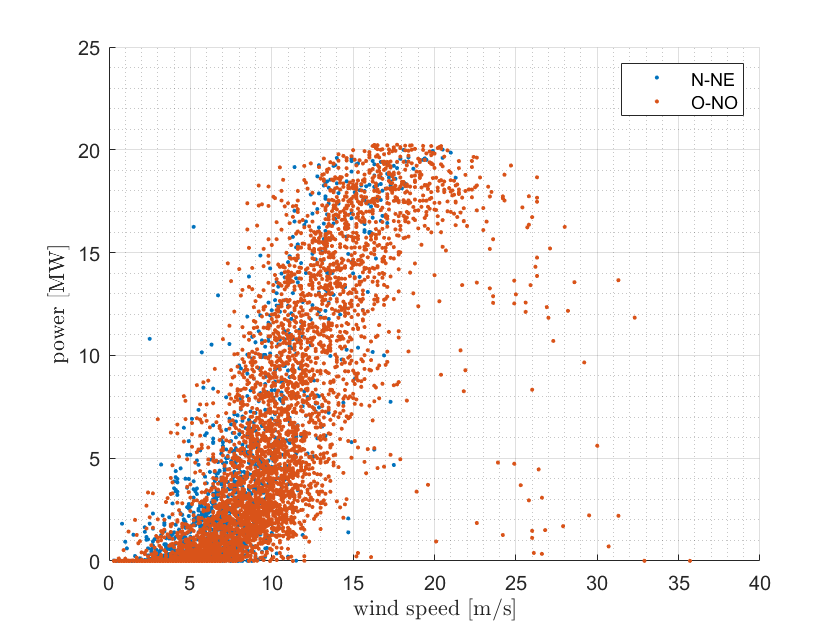

% Plot scatter plots of p(ws)
figure(1)
for i = [1,10]
    scatter(Ws1_sector{i},p_sector{i},'.')
    hold on
end
xlabel('wind speed [m/s]',"Interpreter","latex")
ylabel('power [MW]',"Interpreter","latex")
legend({'N-NE','O-NO'})
grid on; grid minor
hold off

## Wind rose

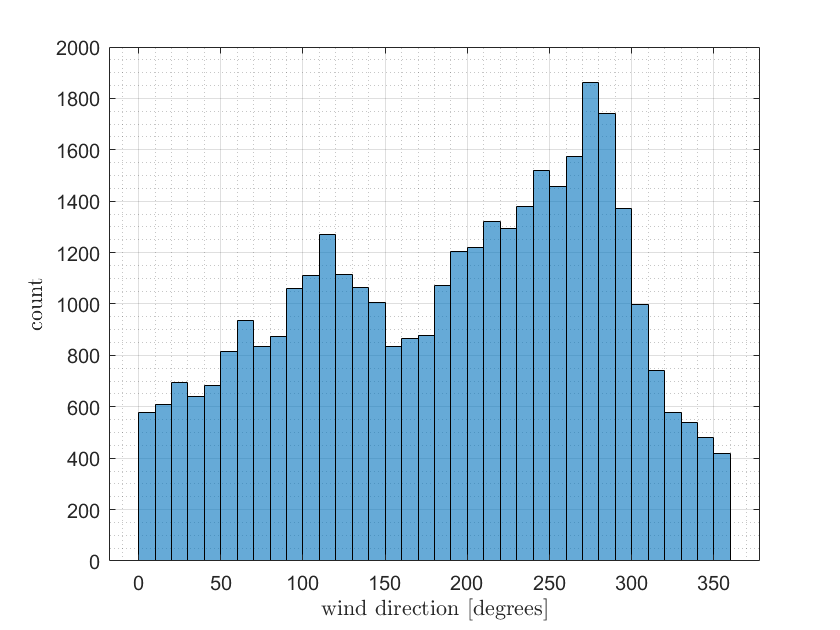

% Wind direction histogram
figure(2)
histogram(Wd1)
grid on; grid minor;
xlabel('wind direction [degrees]',"Interpreter","latex")
ylabel('count',"Interpreter","latex")

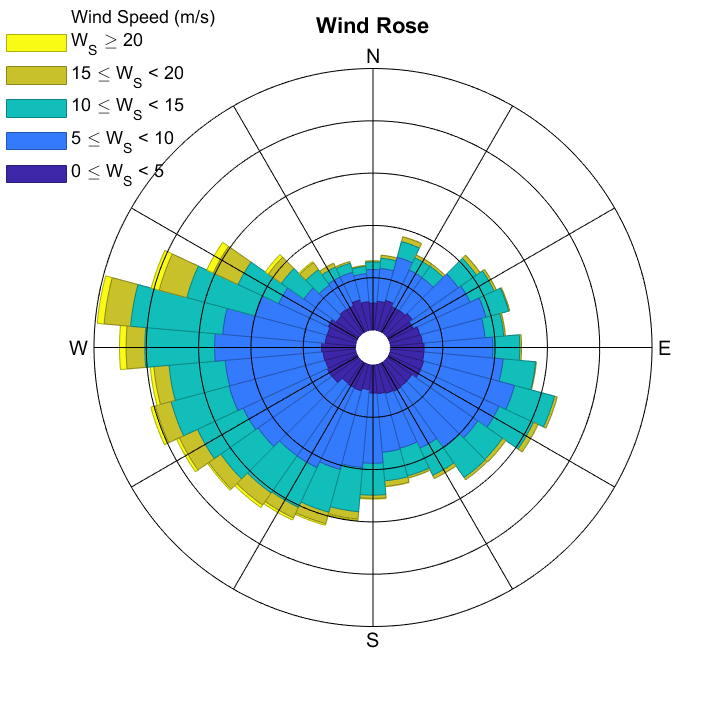


% Wind rose
figure(3)
WindRose(90-mod(Wd1,360),Ws1,"vWinds", [0 5 10 15 20], ...
    "lablegend", "Wind Speed (m/s)");
%title('Klim power site - 70m')
hold off


% Empty figure to reset the figure size
figure(4)

The wind is comming mostly from the West. If this is considered correctly by the wind farm design, the highest power curve should be obtained for that direction.

## Estimation of the power curves with local polynomial regression

% Regression parameters
points = 100;             % grid resolution on axis Ws
order = 3;                % order of the fitted polynomials
h = 0.5;                    % bandwidth [0 to 1]

% Perform regression for each sector
Ws1_reg = cell(12,1);
p_reg = cell(12,1);
for i = 1:12
    [Ws1_reg{i},p_reg{i}] = regsmooth1D([Ws1_sector{i},p_sector{i}], points, order ,h);
end

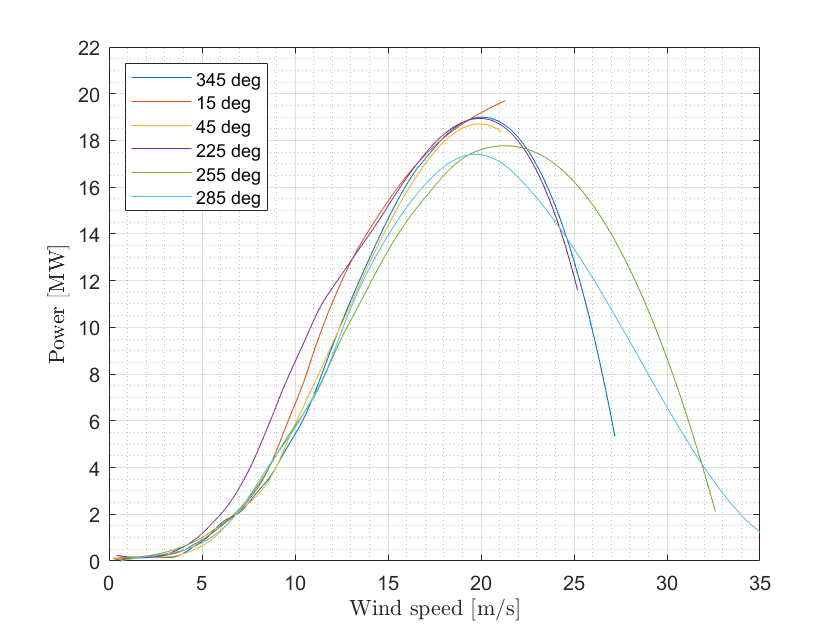

% Plot the regression p(ws)
figure(5)
for i = [12, 1, 2, 8, 9, 10]
    plot(Ws1_reg{i},p_reg{i},"DisplayName",strcat(num2str(i*30-15)," deg"))
    hold on
end
grid on; grid minor
xlabel('Wind speed [m/s]',"Interpreter","latex")
ylabel('Power [MW]',"Interpreter","latex")
axis([0 35 0 22])
legend("Location","northwest")
hold off

## Cross validation on the test set   

% Size of test set
len_test = length(t)-len_train;

% Regression parameters
points = 100;             % grid resolution on axis Ws
order = 3;                % order of the fitted polynomials
h = 0.1:0.1:1;                    % bandwidth [0 to 1]

% Initialize RMSE
RMSE = zeros(length(h),1);
% Loop over the bandwidth
for j = 1:length(h)

    % Perform regression for each sector
    Ws1_reg = cell(12,1);
    p_reg = cell(12,1);
    for i = 1:12
        [Ws1_reg{i},p_reg{i}] = regsmooth1D([Ws1_sector{i},p_sector{i}], points, order ,h(j));
    end
    
    % Initialize estimations and errors
    p_est = zeros(len_test,1);
    error = zeros(len_test,1);
    % Realize estimations over the test set
    for i = 1:len_test
        sector = ceil(Wd1_test(i)/30+0.000001); % Sector of current point
        p_est(i) = interp1(Ws1_reg{sector},p_reg{sector},Ws1_test(i));
        error(i) = p_est(i) - p_test(i);
    end
    RMSE(j) = sqrt(mean(error.^2,'omitnan'));
    X = sprintf('bandwidth = %s ; RMSE = %d',h(j),RMSE(j));
    disp(X)
end

bandwidth = 1.000000e-01 ; RMSE = 2.232570e+00
bandwidth = 2.000000e-01 ; RMSE = 2.225623e+00
bandwidth = 3.000000e-01 ; RMSE = 2.222563e+00
bandwidth = 4.000000e-01 ; RMSE = 2.220080e+00
bandwidth = 5.000000e-01 ; RMSE = 2.218364e+00
bandwidth = 6.000000e-01 ; RMSE = 2.216403e+00
bandwidth = 7.000000e-01 ; RMSE = 2.214367e+00
bandwidth = 8.000000e-01 ; RMSE = 2.212216e+00
bandwidth = 9.000000e-01 ; RMSE = 2.210345e+00
bandwidth =  ; RMSE = 2.210802e+00


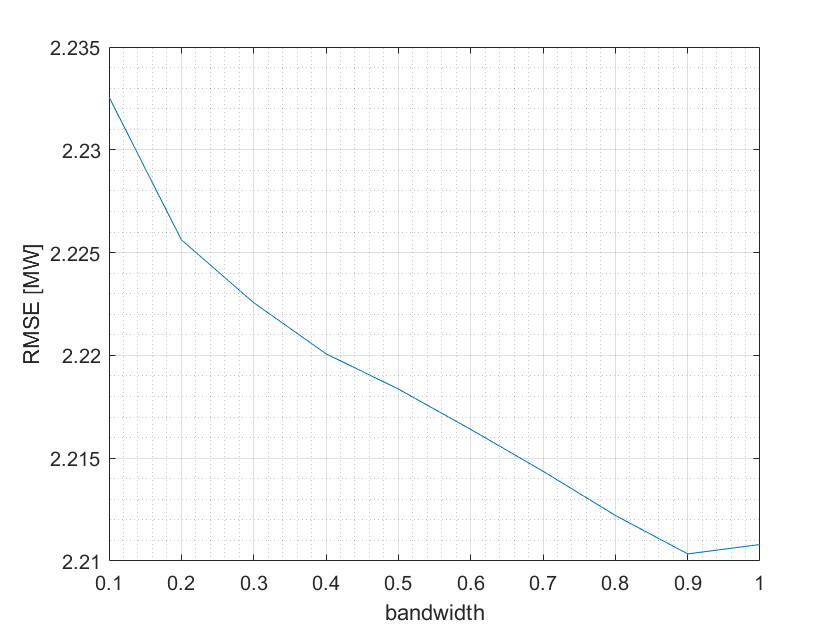

% Plot the RMSE for bandwidth selection
figure(6)
plot(h,RMSE)
xlabel('bandwidth')
ylabel('RMSE [MW]')
grid on; grid minor


% 95% confidence interval for h=0.9
% number of observations large 
% => normal distribution and not necessary student
CI = [RMSE(9)*norminv(0.025),RMSE(9)*norminv(0.975)]

CI =    -4.3322    4.3322


**The advandage of using local regression is that a relation can be obtained between ws and p so that for a forecast 48h ahead for ws, it is possible to estimate p. The confidence interval given includes the errors coming from the NWP model for only one hour ahead.**